clear; clc; close all; fclose all;

**Generate Pilot Subcarriers:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 2
rng default
pilot_data_m2 = randsrc(4096/4*16,1,0:2-1);
file = fopen('../Xilinx/Sw_Source/ofdm/files/PilotDataM2.txt','wt');
fprintf(file, "%d\n", pilot_data_m2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 4
rng default
pilot_data_m4 = randsrc(4096/4*16,1,0:4-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM4.txt','wt');
fprintf(file, "%d\n", pilot_data_m4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 16
rng default
pilot_data_m16 = randsrc(4096/4*16,1,0:16-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM16.txt','wt');
fprintf(file, "%d\n", pilot_data_m16);
fclose('all');

**OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from TX Frequency file header
file = fopen('../Xilinx/SW_Source/ofdm/files/TxFreqData1.txt','r');
nfft = fscanf(file,"%d,",1);
BW = fscanf(file,"%d,",1);
cp_len = fscanf(file,"%d,",1);
M = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
tx_scale = fscanf(file,"%d,",1);
first_pilot_carrier = fscanf(file,"%d,",1);
last_pilot_carrier = fscanf(file,"%d,",1);
freq_data_ofdm = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%d");
    tmp_q = fscanf(file,",%d");
    tmp_iq = complex(tmp_i, tmp_q);
    freq_data_ofdm = [freq_data_ofdm tmp_iq];
end
freq_data_ofdm_1 = reshape(freq_data_ofdm,[nfft ofdm_symbols]);

pilot_density = 0.25; % Hardcoded value
DAC_FS = 10000000; % Hardcoded value
nfft_p = 4*nfft; % For plotting spectrum

**Calculated OFDM Parameters:**

rep = 1/pilot_density;
zp_index = [1:first_pilot_carrier,last_pilot_carrier+2:nfft];
pilot_index = first_pilot_carrier+1:rep:last_pilot_carrier+1;
data_index = 1:nfft;
data_index([pilot_index,zp_index]) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
zp_carriers = length(zp_index);
data_carriers = length(data_index);
n_packed = nfft*M;
Fs = BW;
Ts = 1/Fs;
Interp_val = DAC_FS/Fs;
F = (-nfft_p/2:nfft_p/2-1)/nfft_p*BW;
F = F/1000; % in kHz
t_up = 0:1/BW/Interp_val:((nfft+cp_len)*ofdm_symbols-1/BW)*1/BW;
F_up = (-nfft_p/2:nfft_p/2-1)/nfft_p*BW*Interp_val;
F_up = F_up/1000;

% For rest of script
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);

**QAM Modulation:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read TX data bits
file = fopen('../Xilinx/SW_Source/ofdm/files/TxModData1.txt','r');
nfft = fscanf(file,"%d",1);
M = fscanf(file,"%d",1);
ofdm_symbols = fscanf(file,"%d",1);
data_char = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');
data = reshape(data_char,[data_carriers ofdm_symbols]);
mod_data = data;

qpsk_mod_data = qammod(data,M);
reference_pilot = qammod(pilot_data,M);
zp_carrier = complex(0,0);

**Insert Pilots:**

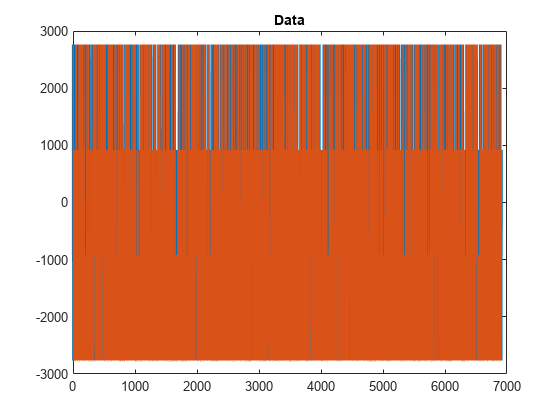

carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qpsk_mod_data;
carriers(zp_index,:) = zp_carrier;
carriers = carriers*tx_scale;

%tmp
p_plot = reshape(qpsk_mod_data*tx_scale,[1 ofdm_symbols*data_carriers]);
p_plot_sw = reshape(freq_data_ofdm_1(data_index,:),[1 ofdm_symbols*data_carriers]);
figure(),plot(real(p_plot),'LineWidth',2),hold on,plot(real(p_plot_sw)),title('Data')

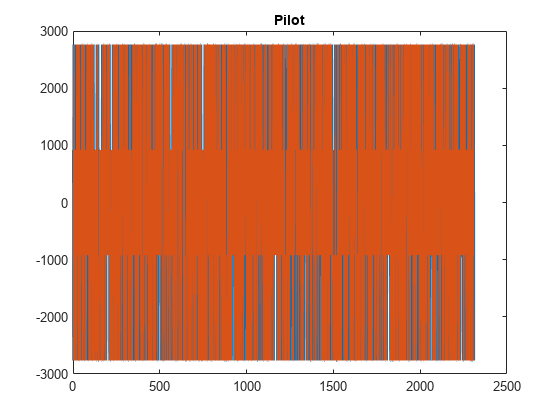

%tmp
p_plot = reshape(reference_pilot*tx_scale,[1 ofdm_symbols*pilot_carriers]);
p_plot_sw = reshape(freq_data_ofdm_1(pilot_index,:),[1 ofdm_symbols*pilot_carriers]);
figure(),plot(real(p_plot),'LineWidth',2),hold on,plot(real(p_plot_sw)),title('Pilot')

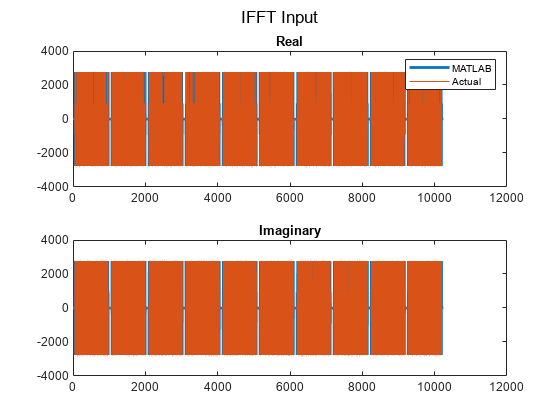


carriers_plot = reshape(carriers,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(carriers_plot),'LineWidth',2),hold on,plot(real(freq_data_ofdm)),legend('MATLAB','Actual'),title('Real')
subplot(2,1,2),plot(imag(carriers_plot),'LineWidth',2),hold on,plot(imag(freq_data_ofdm)),title('Imaginary'),sgtitle('IFFT Input')

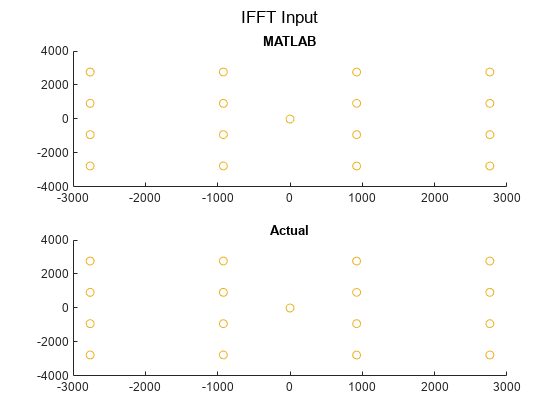

figure(),subplot(2,1,1),scatter(real(carriers),imag(carriers)),title('MATLAB')
subplot(2,1,2),scatter(real(freq_data_ofdm_1),imag(freq_data_ofdm_1)),title('Actual'),sgtitle('IFFT Input')

**Perform IFFT and CP Insertion:**

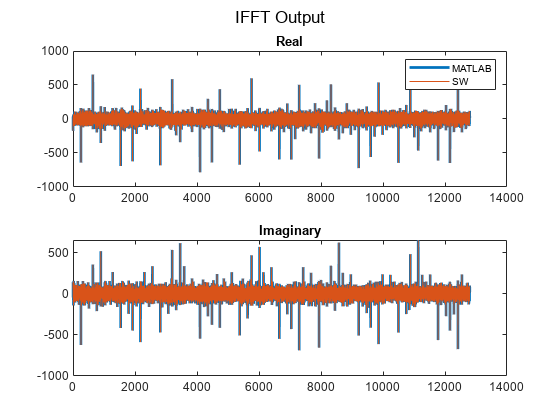

cp_start = nfft-cp_len;
ifft_sub_carriers = ifft((carriers),nfft);
cp = ifft_sub_carriers(cp_start+1:end,:);
ofdm_tx_signal_par = vertcat(cp,ifft_sub_carriers);

file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information')
end
ifft_sw = [];
for i=1:(nfft+cp_len)*ofdm_symbols
    tmp_i = fscanf(file,"%f");
    tmp_q = fscanf(file,",%f");
    tmp_iq = complex(tmp_i, tmp_q);
    ifft_sw = [ifft_sw tmp_iq];
end
fclose('all');

% Plot
ofdm_tx_signal_re = reshape(ofdm_tx_signal_par,[1 ofdm_symbols*(nfft+cp_len)]);
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(real(ifft_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(imag(ifft_sw)),title('Imaginary'),sgtitle('IFFT Output')

**Parallel to Serial:**

ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[(nfft+cp_len)*ofdm_symbols 1]);

**DUC:**

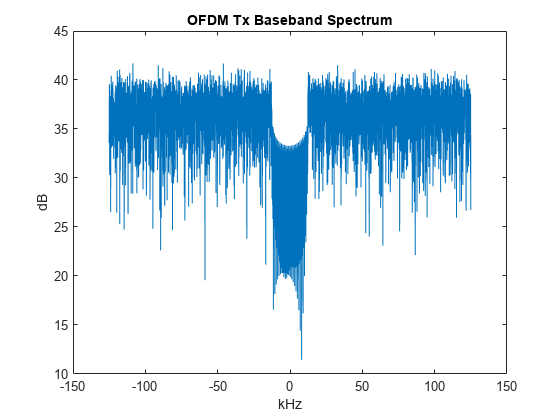

file = fopen('../Xilinx/SW_Source/ofdm/files/TxDuc1.txt','r');
Fc = fscanf(file,"%d,\n",1);
Fc = Fc * 1000;
Interp_val = fscanf(file,"%d,\n",1);
fclose('all');

figure(),plot(F,10*log10(abs(fftshift(fft(ofdm_tx_signal_ser,nfft_p))))),title('OFDM Tx Baseband Spectrum'),xlabel('kHz'),ylabel('dB')

ofdm_duc_signal = interp(ofdm_tx_signal_ser,Interp_val,10,1);
ofdm_duc_signal = ofdm_duc_signal.';

**IQ Mixer:**

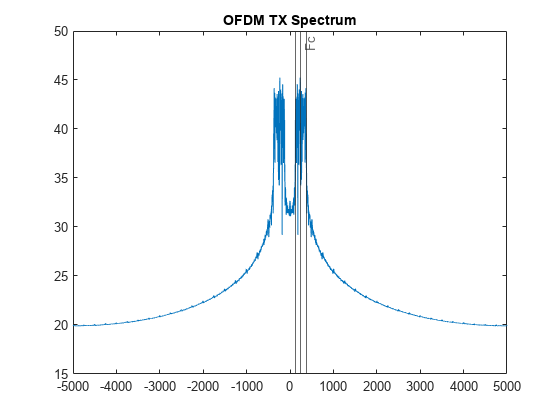

ofdm_duc_signal_i = real(ofdm_duc_signal) .* cos(2*pi*Fc*t_up);
ofdm_duc_signal_q = imag(ofdm_duc_signal) .* -sin(2*pi*Fc*t_up);
ofdm_duc_signal_real = ofdm_duc_signal_i + ofdm_duc_signal_q;

figure(),plot(F_up,10*log10(abs(fftshift(fft(ofdm_duc_signal_real,nfft_p))))),title('OFDM TX Spectrum'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})

**Channel:**

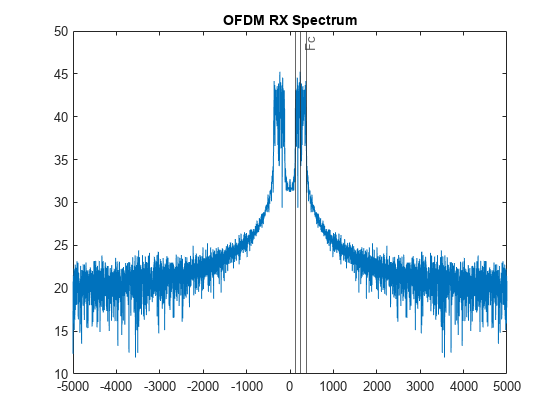

% AWGN
SNR = 35;
ofdm_tx_signal_ch = awgn(ofdm_duc_signal_real,SNR,'measured');
% Multipath
multipath = [1 0.1 0.05 0 0 0 0 0];
%ofdm_tx_signal_ch = filter(multipath,1,ofdm_tx_signal_ch);

figure(),plot(F_up,10*log10(abs(fftshift(fft(ofdm_tx_signal_ch,nfft_p))))),title('OFDM RX Spectrum'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})

**IQ Mixer:**

i_ddc = ofdm_tx_signal_ch .* cos(2*pi*Fc*t_up);
q_ddc = ofdm_tx_signal_ch .* -sin(2*pi*Fc*t_up);
ddc_signal = complex(i_ddc,q_ddc);

**DDC:**

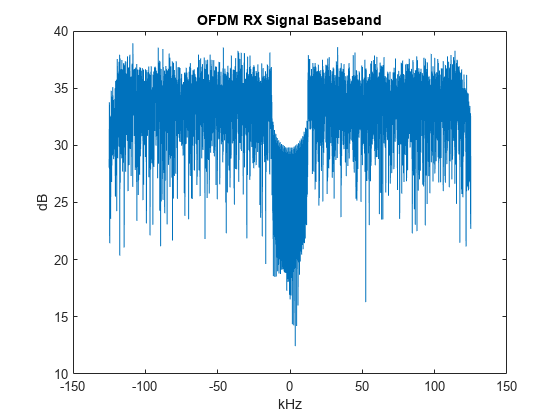

ddc_base_signal = decimate(ddc_signal,Interp_val,4096,'Fir'); %Normal
figure(),plot(F,10*log10(abs(fftshift(fft(ddc_base_signal,nfft_p))))),title('OFDM RX Signal Baseband'),xlabel('kHz'),ylabel('dB')

ofdm_rx_signal_ch = ofdm_tx_signal_ser;
ofdm_rx_signal_ch = filter(multipath,1,ofdm_rx_signal_ch);
%ofdm_rx_signal_ch = ddc_base_signal; % From DDC

**Serial to Parallel:**

ofdm_rx_signal_par = reshape(ofdm_rx_signal_ch,[nfft+cp_len ofdm_symbols]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Write simulated channel signal to file
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftInjectData1.txt','wt');
fprintf(file,"%d,\n",nfft);
fprintf(file,"%d,\n",cp_len);
fprintf(file,"%d,\n",ofdm_symbols);
for i = 1:ofdm_symbols*(nfft+cp_len)
    fprintf(file,"%0.6f, %0.6f\n",real(ofdm_rx_signal_ch(i)),imag(ofdm_rx_signal_ch(i)));
end
fclose('all');

**CP Removal:**

cp_rm_signal = ofdm_rx_signal_par;
cp_rm_signal(1:cp_len,:) = [];


**FFT Output:**

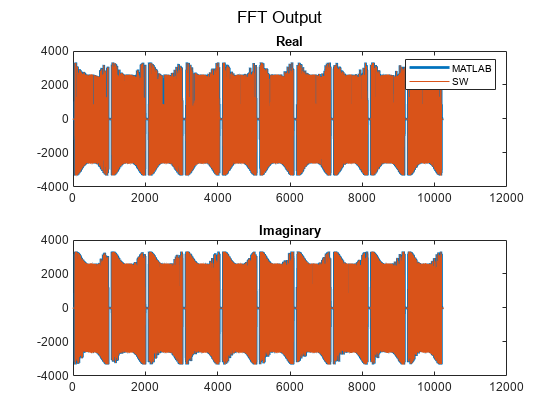

fft_signal = (fft(cp_rm_signal,nfft));

file = fopen('../Xilinx/SW_Source/ofdm/files/RxFreqData1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information');
end
Fft_data_sw = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    Fft_data_sw = [Fft_data_sw tmp_iq];
end

fft_signal_re = reshape(fft_signal,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(fft_signal_re),'LineWidth',2),hold on,plot(real(Fft_data_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(fft_signal_re),'LineWidth',2),hold on,plot(imag(Fft_data_sw)),title('Imaginary'),sgtitle('FFT Output')

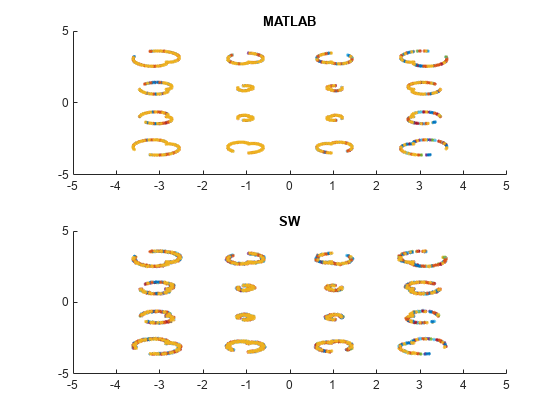

Fft_data_sw = reshape(Fft_data_sw,[nfft, ofdm_symbols]);
Fft_data_sw(zp_index,:) = [];
fft_signal(zp_index,:) = [];

lim = sqrt(M)+1;
y_lim = [-lim lim]; x_lim = [-lim lim];
figure(),subplot(2,1,1),scatter(real(fft_signal/tx_scale),imag(fft_signal/tx_scale),'.'),title('MATLAB'),ylim(y_lim),xlim(x_lim)
subplot(2,1,2),scatter(real(Fft_data_sw/tx_scale),imag(Fft_data_sw/tx_scale),'.'),title('SW'),ylim(y_lim),xlim(x_lim)

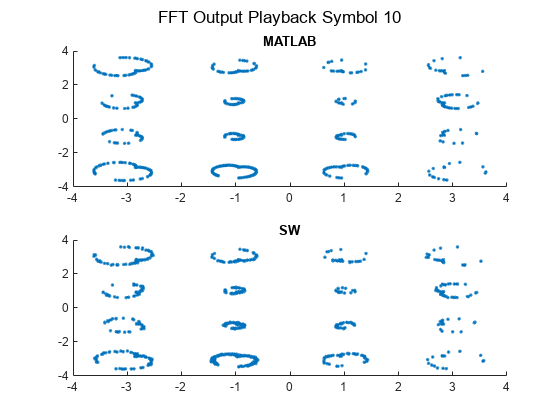

figure()
for i = 1:ofdm_symbols
    subplot(2,1,1),scatter(real(fft_signal(:,i)/tx_scale),imag(fft_signal(:,i)/tx_scale),'.')
    title('MATLAB')
    subplot(2,1,2),scatter(real(Fft_data_sw(:,i)/tx_scale),imag(Fft_data_sw(:,i)/tx_scale),'.')
    title('SW')
    sgtitle(['FFT Output Playback Symbol ',num2str(i)])
    pause(0.1);
end

**Equalization:**

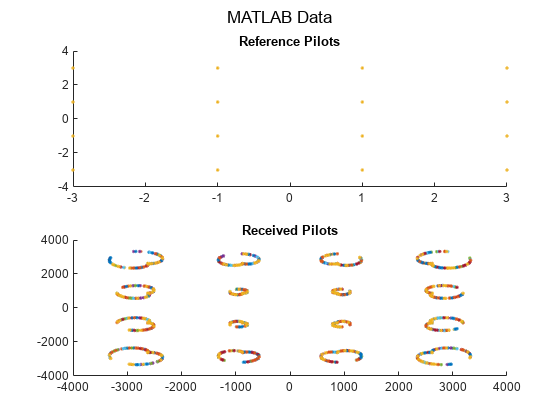

fft_signal_eq = fft_signal;
P_RX = fft_signal_eq(pilot_index-first_pilot_carrier,:);
figure(),subplot(2,1,1),scatter(real(reference_pilot),imag(reference_pilot),'.'),title('Reference Pilots')
subplot(2,1,2),scatter(real(P_RX),imag(P_RX),'.'),title('Received Pilots'),sgtitle('MATLAB Data')

% Get Channel Estimate
%P_RX = P_RX / tx_scale;
%reference_pilot = reference_pilot*tx_scale;
P_RX_re = real(P_RX); P_RX_im = imag(P_RX); P_re = real(reference_pilot); P_im = imag(reference_pilot);
P_RX_im = -P_RX_im; P_im = -P_im;
H = (P_RX_re.*P_re + P_RX_im.*P_im)./(P_re.^2 + P_im.^2) + 1i*(P_RX_im.*P_re - P_RX_re.*P_im)./(P_re.^2 + P_im.^2);
H_ZF_interp = interp1(pilot_index-first_pilot_carrier,H,1:(data_carriers+pilot_carriers),'previous');
if (last_pilot_carrier+1 ~= pilot_index(end))
    disp('Pilots do no wrap, setting last pilot to previous pilot')
    H_ZF_interp(end,:) = H_ZF_interp(end-1,:);
end

Pilots do no wrap, setting last pilot to previous pilot


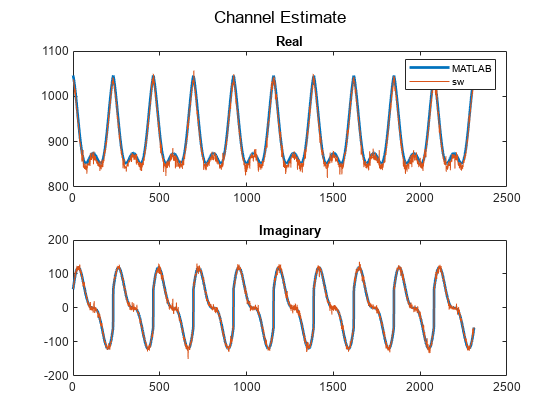

H_ZF_re = real(H_ZF_interp); H_ZF_im = imag(H_ZF_interp);fft_re = real(fft_signal_eq);fft_im = imag(fft_signal_eq);
H_ZF_im = -H_ZF_im;
% Equalize
Z_EQ_ZF = (fft_re.*H_ZF_re + fft_im.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2) + 1i*(fft_im.*H_ZF_re - fft_re.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2);
fft_signal_eq(pilot_index-first_pilot_carrier,:) = [];
Z_EQ_ZF(pilot_index-first_pilot_carrier,:) = [];

Fft_data_sw_eq = Fft_data_sw;
Fft_data_sw_eq(pilot_index-first_pilot_carrier,:) = [];

file = fopen('../Xilinx/SW_Source/ofdm/files/ChannelEstimate1.txt','r');
H_sw = [];
for i = 1:pilot_carriers*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    H_sw = [H_sw tmp_iq];
end
H_plot = reshape(H,[1 ofdm_symbols*pilot_carriers]);
figure(),subplot(2,1,1),plot(real(H_plot),'LineWidth',2),hold on,plot(real(H_sw)),legend('MATLAB','sw'),title('Real')
subplot(2,1,2),plot(imag(H_plot),'LineWidth',2),hold on,plot(imag(H_sw)),title('Imaginary'),sgtitle('Channel Estimate')

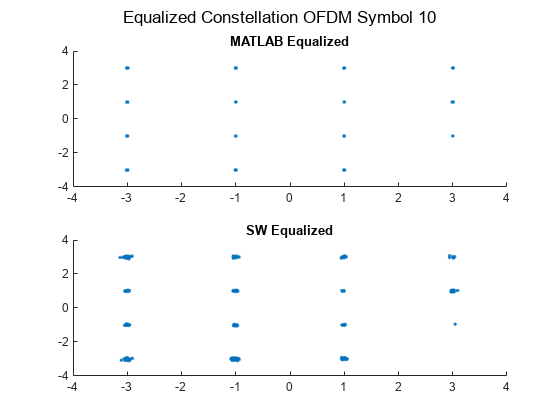

file = fopen('../Xilinx/SW_Source/ofdm/files/RxFreqDataEQ1.txt','r');
nfft_tmp = fscanf(file,"%d,\n",1);
M_tmp = fscanf(file,"%d,\n",1);
ofdm_symbols_tmp = fscanf(file,"%d,\n",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with Header information')
end
EQ_sw = [];
for i = 1:(data_carriers+pilot_carriers)*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    EQ_sw = [EQ_sw tmp_iq];
end
Z_EQ_ZF_plot = reshape(Z_EQ_ZF,[1 ofdm_symbols*data_carriers]);
EQ_sw = reshape(EQ_sw,[data_carriers+pilot_carriers ofdm_symbols]);
EQ_sw(pilot_index-first_pilot_carrier,:) = [];
EQ_sw_plot = reshape(EQ_sw,[1 ofdm_symbols*data_carriers]);

figure()
for i = 1:ofdm_symbols
    %subplot(3,1,1),scatter(real(fft_signal_eq),imag(fft_signal_eq),'.'),title('MATLAB no Equalization')
    subplot(2,1,1),scatter(real(Z_EQ_ZF(:,i)),imag(Z_EQ_ZF(:,i)),'.'),title('MATLAB Equalized')
    subplot(2,1,2),scatter(real(EQ_sw(:,i)),imag(EQ_sw(:,i)),'.'),title('SW Equalized')
    sgtitle(['Equalized Constellation OFDM Symbol ',num2str(i)])
    pause(0.1)
end

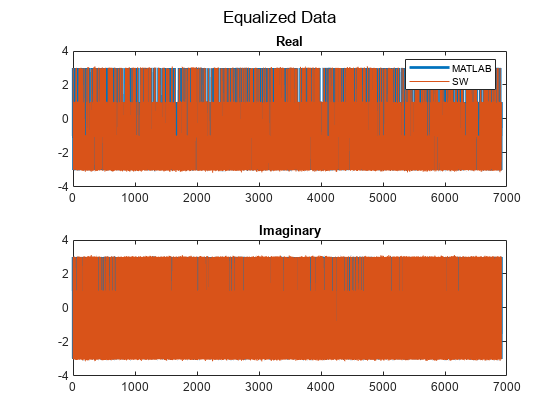

figure(),subplot(2,1,1),plot(real(Z_EQ_ZF_plot),'LineWidth',2),hold on,plot(real(EQ_sw_plot)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(Z_EQ_ZF_plot),'LineWidth',2),hold on,plot(imag(EQ_sw_plot)),title('Imaginary'),sgtitle('Equalized Data')

**QAM Demodulation:**

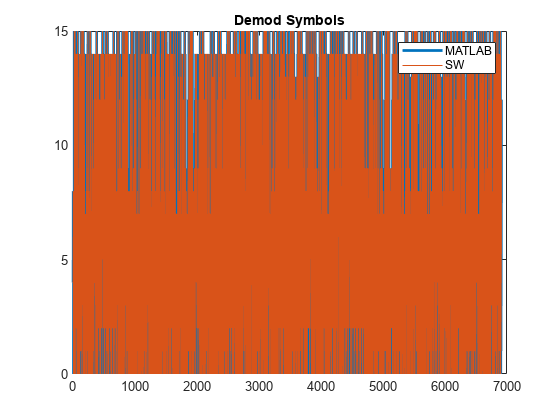

demod_data = qamdemod(Z_EQ_ZF,M);
demod_sw = qamdemod(EQ_sw,M);

demod_data_plot = reshape(demod_data,[1 ofdm_symbols*data_carriers]);
demod_sw_plot = reshape(demod_sw,[1 ofdm_symbols*data_carriers]);
figure(),plot(demod_data_plot,'LineWidth',2),hold on,plot(demod_sw_plot),legend('MATLAB','SW'),title('Demod Symbols')

**Error Rate:**

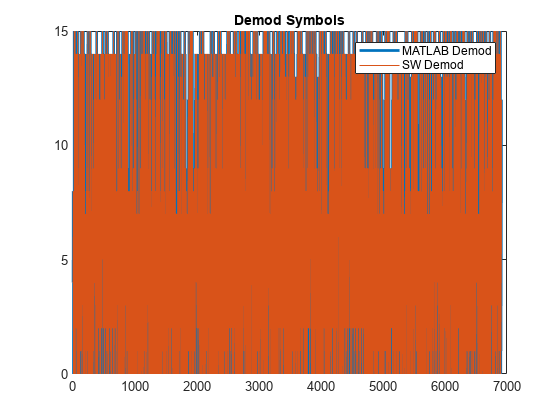


file = fopen('../Xilinx/SW_Source/ofdm/files/RxDemodData1.txt','r');
nfft_tmp = fscanf(file,"%d",1);
M_tmp = fscanf(file,"%d",1);
ofdm_symbols_tmp = fscanf(file,"%d",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with header information');
end
data_char_rx = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');

figure(),plot(demod_sw_plot,'LineWidth',2),hold on,plot(data_char_rx),legend('MATLAB Demod','SW Demod'),title('Demod Symbols')


ser_sw = symerr(data_char, data_char_rx)/numel(data_char);
ser_mat = symerr(data, demod_data)/numel(data);

**Analysis:**

evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[mat_evm mat_evm_pk] = evm(qpsk_mod_data,Z_EQ_ZF);
[sw_evm sw_evm_pk] = evm(qpsk_mod_data,EQ_sw);

Equalization = ["MATLAB";"SW"];
SER = [ser_mat;ser_sw];
AverageEVM = [mat_evm;sw_evm];
PeakEVM = [mat_evm_pk;sw_evm_pk];
figure(),table(Equalization,SER,AverageEVM,PeakEVM)

ans = 2×4 table
    Equalization    SER    AverageEVM    PeakEVM
    ____________    ___    __________    _______

      "MATLAB"       0      0.17348      0.43371
      "SW"           0       1.2283       5.2226


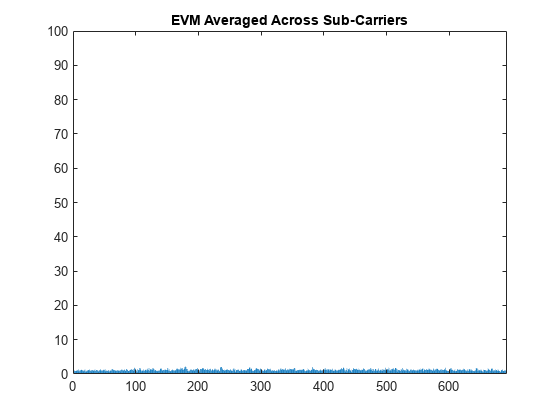

evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data,EQ_sw);
y_lim = [0 100];
y = 1:data_carriers;
figure(),bar(y,sw_evm),title('EVM Averaged Across Sub-Carriers'),ax = gca; ax.YLim = y_lim;

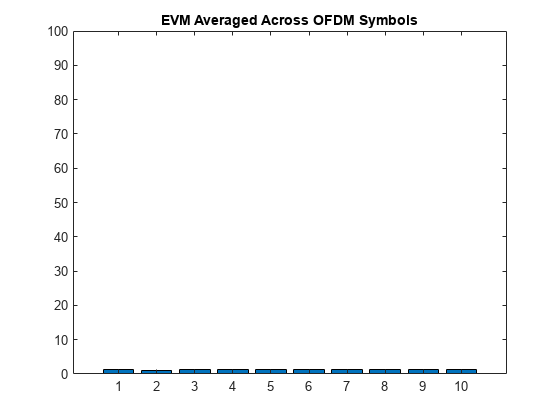

evm = comm.EVM(AveragingDimensions=1);
sw_evm = evm(qpsk_mod_data,EQ_sw);
y = 1:ofdm_symbols;
figure(),bar(y,sw_evm),title('EVM Averaged Across OFDM Symbols'),ax = gca; ax.YLim = y_lim;